## Tutorial 1: A Spherical Mesh

This tutorial assumes prior knowledge of and confidence with usage of the EIDORS software. For more information about any of the methods or functions, see the specific documentation for that method or function.

### Initialisation of the FEM

First the finite element mesh (FEM) is created using the 'Sphere' class, we call the object 'sphere' and set the contact impedance to 1000 ohms. The conductivity distribution is set to a 4-shell head model automatically. Information about the mesh and the conductivity distribution can then be viewed.

clear;
sphere = Sphere(1000); %argument is contact impedance in ohms
sphere.show_mesh_info; 

    Mesh_Type     Radius    Number_of_Elements    Number_of_Nodes    Number_of_Electrodes    Contact_Impedance
    __________    ______    __________________    _______________    ____________________    _________________

    {'Sphere'}     0.1            15255                3851                   19                   1000       



sphere.show_conductivity_info;

    Conductivity_Value    Number_of_Elements
    __________________    __________________

          0.0042                 4260       
             0.3                10023       
               1                  972       



The mesh can now be viewed, whether the conductivity distribution is shown by colouring the elements can be toggled.

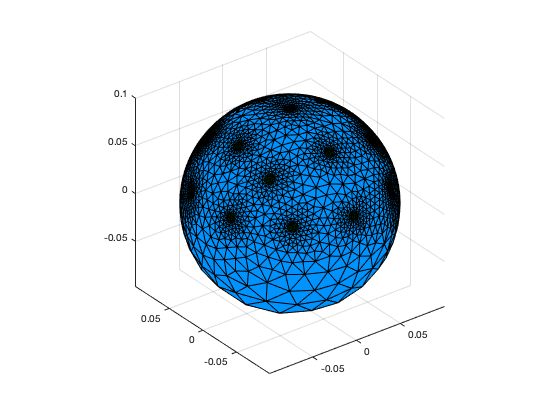

sphere.show_mesh(true); %argument determines whether elements are coloured according to conductivity

Next a stimulation pattern is saved for the mesh. An adjacent stimulation pattern with a 1mA stimulation amplitude is chosen.

sphere = sphere.assign_stimulation_pattern(EEG_10_20_stim('adjacent', 1e-3)); %1st argument indicates adjacent stimulation pattern, 2nd argument is stimulation amplitude in Amps.

Magnetic field sensor locations for the mesh are now saved, 50 evenly spaced sensors above the top hemisphere are chosen at a radial distance of 5mm.

sphere = sphere.fibonacci_hemisphere_magnetic_field_sensors(50, 0.105); %first argument is number of sensors, 2nd argument is radial distance of sensors from centre of mesh.

The mesh with the magnetic field sensors can now be viewed.

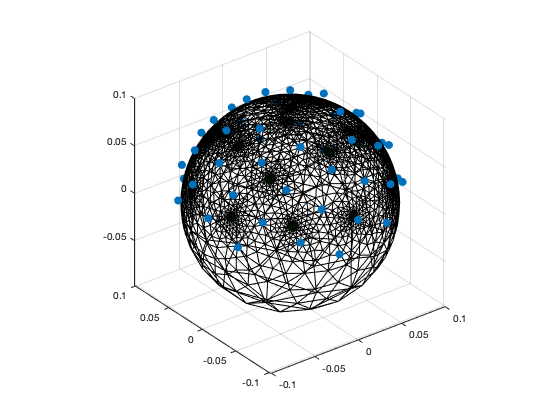

sphere.show_mesh_with_sensors;

A perturbation can be inserted, the perturbation is of 2cm radius with an offset  from the centre of the mesh of +4cm along the z-axis and a conductivity increase of 1%, all elements not corresponding to grey or white matter will be excluded. 

sphere = sphere.insert_perturbation(0.02, [0,0,0.04], 1, true); %1st argument is radius of perturbation, 2nd argument is offset of perturbation from centre of mesh,
%3rd argument is percentage increase in conductivity of perturbation, 4th argument determines whether only grey/white matter elements are included.

The mesh with the perturbation can now be viewed, the perturbation is highlighted in red. The perturbation does not appear to be spherical due to the coarse mesh density.

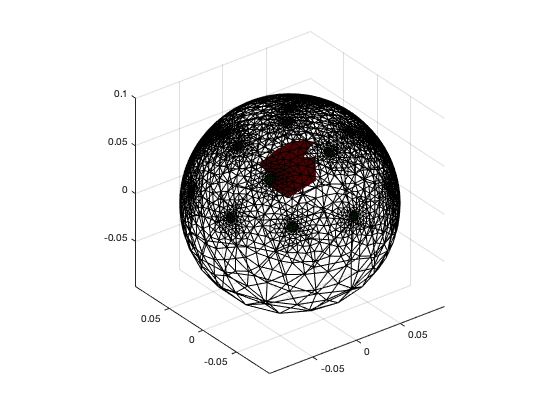

sphere.show_mesh_perturbation(1); %argument indexes the perturbation to be considered

More perturbations can be inserted.

sphere = sphere.insert_perturbation(0.02, [0.02,0,0.01], 2, true);
sphere = sphere.insert_perturbation(0.03, [0,0.02,0.02], 3, true);

Information about all saved perturbations can then be viewed in a table. The perturbation number is how to reference that specific perturbation when calling other functions which take the perturbation number as an input.

sphere.display_perturbations;

    Perturbation_number          Location          Radius    Conductivity_Increase_Percentage      Volume      Number_of_elements
    ___________________    ____________________    ______    ________________________________    __________    __________________

             1                0       0    0.04     0.02                    1                    3.0852e-05            14        
             2             0.02       0    0.01     0.02                    2                    2.2265e-05             5        
             3                0    0.02    0.02     0.03                    3                    0.00011209            42        



Perturbations can also be removed from the saved set by referencing them with their perturbation number.

sphere = sphere.remove_perturbation(2); %argument indexes the perturbation to be considered

The perturbation information table can then be viewed and it can be seen that perturbation number 2 from the previous table has been deleted. Note: doing this will renumber the perturbations.

sphere.display_perturbations;

    Perturbation_number        Location         Radius    Conductivity_Increase_Percentage      Volume      Number_of_elements
    ___________________    _________________    ______    ________________________________    __________    __________________

             1             0       0    0.04     0.02                    1                    3.0852e-05            14        
             2             0    0.02    0.02     0.03                    3                    0.00011209            42        



### Solving a forward problem for the unperturbed case

The standing magnetic field for all different injection pairs for the chosen stimulation pattern, stimulation amplitude and magnetic field sensor locations can be found. Whether the magnetic field is calculated in scalar or vector form can be chosen, vector is chosen in this case. 

sphere = sphere.standing_field('vector'); %argument determines whether the data is output in vector or scalar form

The data is stored in: 

sphere.standing_field_data

and is labelled appropriately.

The standing field lines can then be shown visually for a chosen stimulation pair, the arrow size can also be modified.

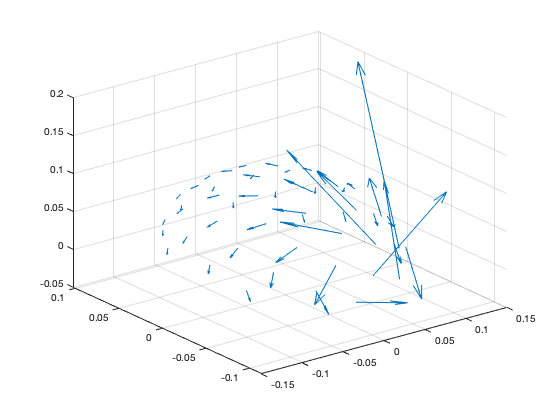

sphere.show_standing_field(3,5); %1st argument indexes the stimulation number to be considered, 2nd argument determines the size of the arrows

###  Solving a magnetic forward problem with a perturbation

The magnetic forward problem can be solved for the mesh with a perturbation and the change in magnetic field found. The perturbation that is considered and whether the magnetic field data is stored in vector or scalar format can be chosen.

sphere = sphere.magnetic_forward_solve(1, 'vector'); %1st argument indexes the perturbation to be considered, 2nd argument determines whether the data is output in scalar or vector form

The data is stored in:

sphere.magnetic_forward_solve_data

and is labelled appropriately.

### Solving an electric forward problem with a perturbation

The electric forward problem can also be solved for a chosen perturbation (although this offers no extra functionality over EIDORS software). 

sphere = sphere.electric_forward_solve(1); %argument indexes the perturbation to be considered

The data is stored in:

sphere.electric_forward_solve_data

and is labelled appropriately.

### Solving the magnetic forward problem for the optimal stimulation

The optimal stimulation is the set consiting of two injection electrodes and one magnetic field sensor which gives the larges signal (change in magnetic field) across all possible stimulation pairs for a chosen perturbation. This can be found as follows, the desired stimulation amplitude must be inputted again.

sphere = sphere.optimal_stimulation_pair(1,1e-3); %1st argument indexes the perturbation to be considered, 2nd argument indicates the stimulation amplitude

The data is stored in 

sphere.optimal_stimulation_data

and is labelled appropriately.

The optimal stimulation set can be viewed

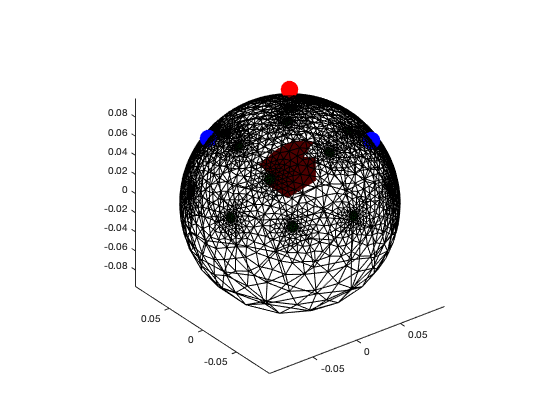

sphere.show_optimal_stim(1); %argument indexes the perturbation to be considered

The red sphere indicates the position of the magnetic field sensor, the blue spheres indicate the positions of the electrodes and the perturbation is highlited. 

### Solving the electric forward problem for the optimal stimulation

The electric optimal stimulation can also be solved, similarly to the magnetic optimal stimulation. 

sphere = sphere.electric_optimal_stimulation_pair(1, 1e-3); %1st argument indexes the perturbation to be considered, 2nd argument indicates the stimulation amplitude

The data is stored in:

sphere.electric_optimal_stimulation_data

and is labelled appropriately.

This optimal stimulation can also be viewed.

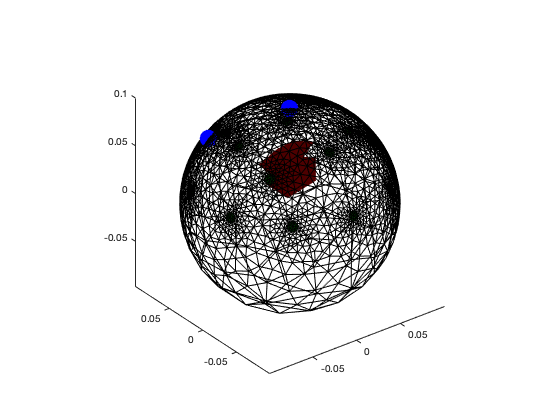

sphere.show_optimal_electric_stim(1); %argument indexes the perturbation to be considered

The positions of the injection electrodes are represented by the blue spheres.

### Finding the voltage on injection electrodes

The voltage on injection electrodes across all stimulation pairs can be found for the provided stimulation pattern.

sphere = sphere.voltage_on_injection_electrodes();

The data is stored in:

sphere.voltages_on_injection_electrodes

in a matrix where each row represents a different stimulation pair and each column represents one of the two injection electrodes. The data are voltages displayed in volts.